# **DEMO:    **7-dof car,  **Simulate** excitations using our Road profile model

## Learning Objectives:

- Explore the car's response when excited by ground excitations produced by our Road Profile model

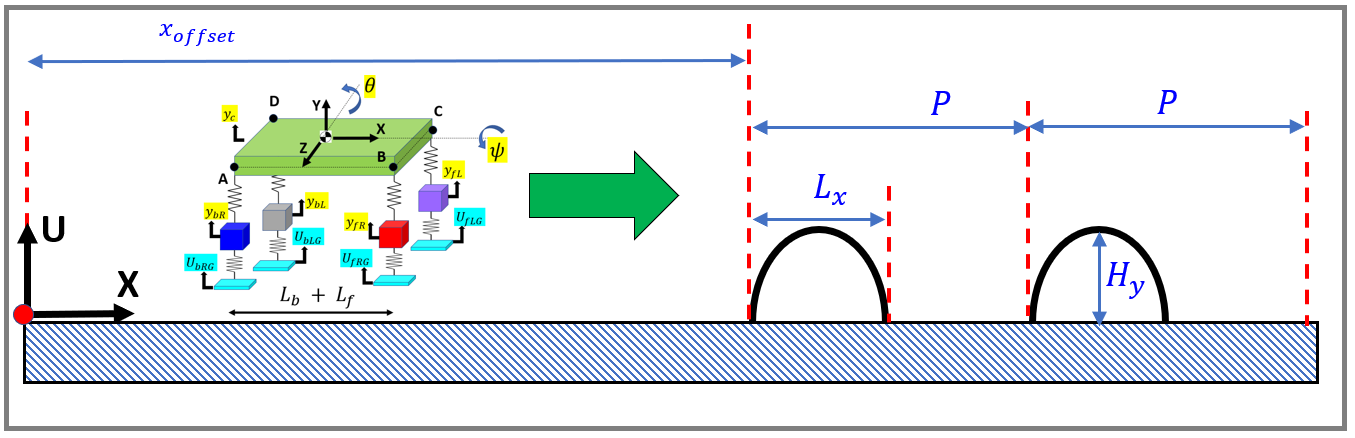

`Bradley Horton : 08-Aug-2021, bhorton@mathworks.com`

## Background

In [`DEMO_bh_test_roads_profile.mlx`](matlab:  edit DEMO_bh_test_roads_profile.mlx) , we defined a **road profile model** that allows us to create a repeating series of "humps" - these humps for example could be "speed humps".  We tested the road profile model with a simple 1-dof car.  Now it's time to stimulate our 7-dof car model with this road profile.

## Read the car parameters

Our car parameters are defined in  an EXCEL file [`bh_7dof_car_database.xlsx`](matlab:  winopen("bh_7dof_car_database.xlsx"))`.`  The data sheet called **"PARAMS_SET_A"** has data that is indicative of a medium sized sedan.

OBJ_car_params =  bh_7dof_car_database_CLS("bh_7dof_car_database.xlsx","PARAMS_SET_A", "IC_SET_A");

The table below lists the parameters that we'll use in our simulation.  

OBJ_car_params.car_tab

ans = 29×4 table
              Name       Value      Units                     Description                
             _______    _______    ________    __________________________________________

    m_c      "m_c"         1500    "kg"        "Mass of car body"                        
    I_cZ     "I_cZ"        1000    "kg.m^2"    "Inertia (Z-axis) of car body"            
    I_cX     "I_cX"         600    "kg.m^2"    "Inertia (X-axis) of car body"            
    m_bR     "m_bR"          80    "kg"        "Mass of back RIGHT wheel and suspension" 
    m_fR     "m_fR"         100    "kg"        "Mass of front RIGHT wheel and suspension"
    m_bL     "m_bL"          80    "kg"        "Mass of back LEFT wheel and suspension"  
    m_fL 

Note also that the system Initial Conditions are defined in the `IC_pos` property.  The order of the DOF vector is:

- `          1      2     3     4      5      6      7`

- `      [ y_c,  theta,  psi,   y_bR,  y_fR,  y_bL,  y_fL ]`

OBJ_car_params.IC_pos'

ans =      0     0     0     0     0     0     0


Open the Simulink model

% open_system("bh_SIM_7dof_car_ROAD_PROFILE.slx")
open_system("bh_SIM_7dof_car_ROAD_PROFILE_only.slx")